clc
clear all

## Reading run file

Here you can import .csv file from the datasets. you should pick as type COLUMN VECTORS. For Cerberus you should add to the data the altitude and the heartrate because Diego likes it. 

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["x2023_09_15T09_12_48", "x1449", "x0", "x431_42", "x20_455", "x1"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "x2023_09_15T09_12_48", "InputFormat", "yyyy-MM-dd'T'HH:mm:ss");

% Import the data
Matilde_15_09_2023_AM = readtable("/home/lorenzo/Documents/Data-Analysis-Policumbent/BM_23/Phoenix/Matilde/Matilde_15_09_2023_AM.csv", opts);

% Convert to output type
x2023_09_15T09_12_48 = Matilde_15_09_2023_AM.x2023_09_15T09_12_48;
altitude = Matilde_15_09_2023_AM.x1449;
cadence = Matilde_15_09_2023_AM.x0;
distance = Matilde_15_09_2023_AM.x431_42;
speed = Matilde_15_09_2023_AM.x20_455;
power = Matilde_15_09_2023_AM.x1;

% Clear temporary variables
clear Matilde_15_09_2023_AM

% Clear temporary variables
clear opts
time = 1:size(power);   % We have a sample every second, easy as it is.

## Data visualization

Just data plotting, remember to add altitude and heartrate for Diego because he likes it.

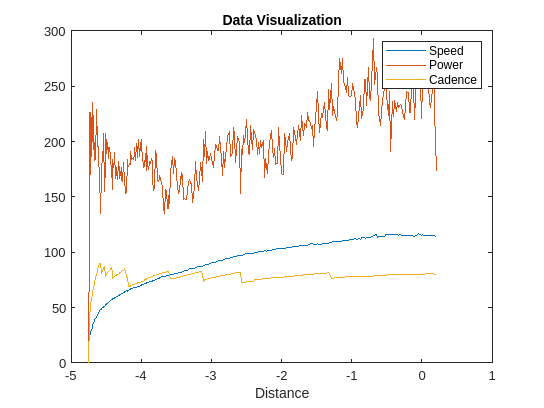

dist_miles = distance/1690 - 5;
plot(dist_miles,speed,dist_miles,power,dist_miles,cadence);
legend("Speed","Power","Cadence");
title("Data Visualization");
xlabel("Distance");

avg_power = mean(power)

avg_power = 198.8812

avg_power_last_km = mean(power(288:end))

avg_power_last_km = 240.8621

## System modeling

sys = [speed,power];
nx = 1;
model = n4sid(sys,nx);

## Simulation

As seen by the real data, the best speed is reached by using an incremental linear power input. Down here you can modify the values of each line of power.

k = size(power,1);
a = 0.829;
b = 1.15;
ScatterFactor = a+(b-a)*rand(k,1);

Here you have to choose the slope of each segment of the power line. The standard coefficients usually fit well but the choice is up to you.

m1 = 1;
m2 = 1;
m3 = 1.1;

Here you can choose the average power input for each segment. The lenght of the ScatterFactor in each segment is measured is seconds and it corresponds to the time each power input has to be maintained by the rider. You can choose the lenght of each segment by modifying t1, t2, t3, t4. 

**The sum of t1, t2, t3, t4 must be k, whitch is the lengh of the training dataset, the s variables do just so.**

t1 = 150; s2 = k-t1;
t2 = 100; s3 = k-t1-t2;
t3 = 94; s4 = k-t1-t2-t3;
t4 = 1; 
x1 = ScatterFactor(1:t1)*200;
x2 = ScatterFactor(1:t2)*160;
x3 = ScatterFactor(1:t3)*190;
x4 = ScatterFactor(1:t4)*140;
%Lore ho provato a mettere lo scatter a 0.85/1.1 giusto per capire quale è
%il valore medio, e ho cambiato i watt [x3,x4], digli di spingere il più
%forte che può sull discesa, anche se scende di tanti W in trappola non è
%un problema (guarda quanti pochi sono in trappola). Ho rimesso poi lo
%scatter come era prima. Ste
y1 = m1*x1;
y2 = x2;
y3 = m2*x3;
y4 = x4;

Just vector concatenation, simulation and plotting.

Sim_power_lin = [y1',y2',y3',y4']';
simSpeed = sim(model,Sim_power_lin);
max_speed = max(simSpeed)

max_speed = 98.7018

trap_speed = simSpeed(end)

trap_speed = 98.7018

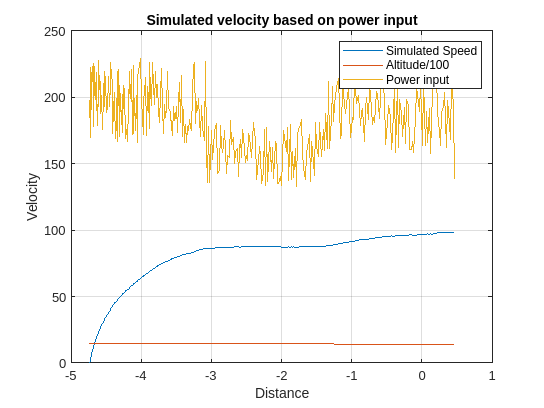

dist_mile = distance/1609;

plot(dist_mile-5, simSpeed,dist_mile-5,altitude/100,dist_mile-5,Sim_power_lin);
title("Simulated velocity based on power input");
legend("Simulated Speed","Altitude/100","Power input");
xlabel("Distance");
ylabel("Velocity");
grid on;